## **Bastankhah & Porte Agél Wake Model Implementation.**

**References**: Design of a Simple Wake Model for the Wind Farm Layout Optimization Considering the Wake Meandering Effect

% Parameters [INPUTS] 
Io = 0.05; % [-] Ambient Turbulence  
D = 0.3; % [m] Rotor Diameter 
Uo = 0.7; % [m/s] Free-Stream Velocity
res_x = 1000; % [-] Distribution X Axis 
res_r = 250; % [-] Distribution Y Axis 
lower_limit_x = 0.75; % [m] 
upper_limit_x = 4.5; % [m] 
lower_limit_r = -1.45; % [m] 
upper_limit_r = 1.45; % [m]
x = linspace(lower_limit_x,upper_limit_x,res_x); % [m] Spatial Vector in X Axis  
r = linspace(lower_limit_r, upper_limit_r, res_r); % [m] Spatial Vector in Y Axis 
Ct = 0.71; % [-] Thrust Coefficient 
a = 0.33; % [-] Axial Induction Factor

#### **Control Vectors**

Coord_x = zeros(res_r,res_x);
Coord_r = zeros(res_r,res_x);
for i=1:res_r
    for j=1:res_x
        Coord_x(i,j)=x(j);
    end
end
for i=1:res_r
    for j=1:res_x
        Coord_r(i,j)=r(i);
    end
end
Coord_x = reshape(Coord_x,[res_r*res_x,1]);
Coord_r = reshape(Coord_r,[res_r*res_x,1]);

#### **BP Model Variables **

gamma = (1/2)*((1+sqrt(1-Ct))/(sqrt(1-Ct)));
epsilon = 0.2*sqrt(gamma); 
I_plus = 0; % For a Single Static Wake [Added Turbulence] 
% I_plus = 0.73*(a^(0.8325))*Io^(0.0325)*(x/D)^(-0.32) Apply For Multiple Wakes
I = sqrt(I_plus^2+Io^2);
k = 0.3837*I + 0.003678;
U_def = zeros(1, res_r*res_x);
for i=1:(res_r*res_x)
    U_def(i) = (1-sqrt(1-((Ct)/(8*(k*(Coord_x(i)/D)+epsilon)^2))))...
        *(1*exp(-((1)/(2*(k*(Coord_x(i)/D)+epsilon)^2))*(Coord_r(i)/D)^2));
end
U_def = U_def';
U_real = Uo.*(1.-U_def);

#### **Plotting Wake Deficit - Velocity Fields**

scatter(Coord_x,Coord_r,100,U_def,'filled');

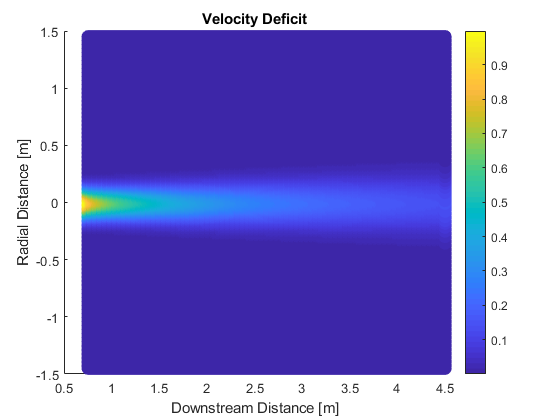

% Velocity Deficit in Far Wake;
title('Velocity Deficit');
xlabel ('Downstream Distance [m]');
ylabel ('Radial Distance [m]');
colorbar;

scatter(Coord_x,Coord_r,100,U_real,'filled');

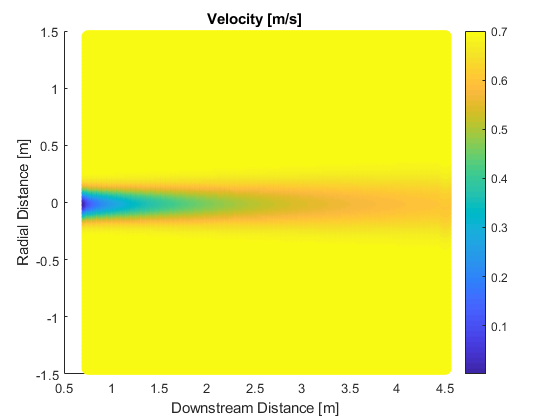

% Velocity in Far Wake;
title ('Velocity [m/s]')
xlabel ('Downstream Distance [m]');
ylabel ('Radial Distance [m]');
colorbar;

#### **Final Matrix of Values  **

Coord_t = [Coord_x, Coord_r, U_def, U_real];